# 1. Parametrelerin Belirlenmesi

Alıcı sistemi ve standart parametreleri

simParams.channelBandwidth = 'CBW20';
Fs = 20e6;                 % 20 MHz örnekleme frekansı
Ts = 1/Fs;                 % Örnekleme periyodu

% --- TEST SENARYOSU PARAMETRELERİ ---
trueCFO = 125000;          % Sinyale eklenecek kasıtlı frekans sapması (Hz) -> 125 kHz
coarsePktOffset = 150;     % Paketin başladığı örnek indeksi (Önceki bloğun çıktısı)
snr_dB = 20;               % Sinyal-Gürültü Oranı (dB)

fprintf('--- Coarse CFO Estimator Testi ---\n\n');

--- Coarse CFO Estimator Testi ---



fprintf('Uygulanan (Gerçek) CFO : %d Hz\n', trueCFO);

Uygulanan (Gerçek) CFO : 125000 Hz


## 2. Sentetik Sinyal Üretimi

L-STF: 16 örneklik sembolün 10 kez tekrarından oluşur

rng(100); % Tekrar edilebilir sonuçlar için
shortSymbol = (randn(16, 1) + 1i*randn(16, 1));
LSTF = repmat(shortSymbol, 10, 1); % Toplam 160 örnek

% Paketin geri kalanı (Rastgele payload)
payload = (randn(300, 1) + 1i*randn(300, 1));

% Temiz temel bant sinyali birleştir (Sadece L-STF ve Payload)
cleanPacket = [LSTF; payload];

## 3. Frekans Sapması (CFO) Enjeksiyonu

Sinyale e^(j*2*pi*f*t) formülü ile faz dönmesi eklenir

t_packet = (0:length(cleanPacket)-1)' * Ts;
packet_with_cfo = cleanPacket .* exp(1i * 2 * pi * trueCFO * t_packet);

## 4. Sinyali Zaman Ekseninde Geciktirme (Offset Ekleme)

Paketin başlangıcından önce sadece gürültü olan bir boşluk ekliyoruz

idleNoise = 0.05 * (randn(coarsePktOffset, 1) + 1i*randn(coarsePktOffset, 1));
rxWaveform_no_noise = [idleNoise; packet_with_cfo];

## 5. AWGN Gürültüsü Ekleme

rxWaveform = awgn(rxWaveform_no_noise, snr_dB, 'measured');

## 6. Fonksiyonun Çağrılması ve Test

Fonksiyonunu çağırıyoruz

estCFO = freqcorrect(rxWaveform, coarsePktOffset, simParams);

## 7. Sonuçların Değerlendirilmesi

error_Hz = abs(trueCFO - estCFO);
error_percent = (error_Hz / trueCFO) * 100;

fprintf('Tahmin Edilen CFO      : %.2f Hz\n', estCFO);

Tahmin Edilen CFO      : 125263.85 Hz


fprintf('Hata Miktarı           : %.2f Hz (%% %.2f)\n\n', error_Hz, error_percent);

Hata Miktarı           : 263.85 Hz (% 0.21)




if error_percent < 5
    fprintf('>> SONUÇ: BAŞARILI! (Hata payı %%5''in altında)\n');
else
    fprintf('>> SONUÇ: BAŞARISIZ! (Hata payı çok yüksek)\n');
end

>> SONUÇ: BAŞARILI! (Hata payı %5'in altında)


## 8. Görselleştirme (Faz Dönmesinin Etkisi)

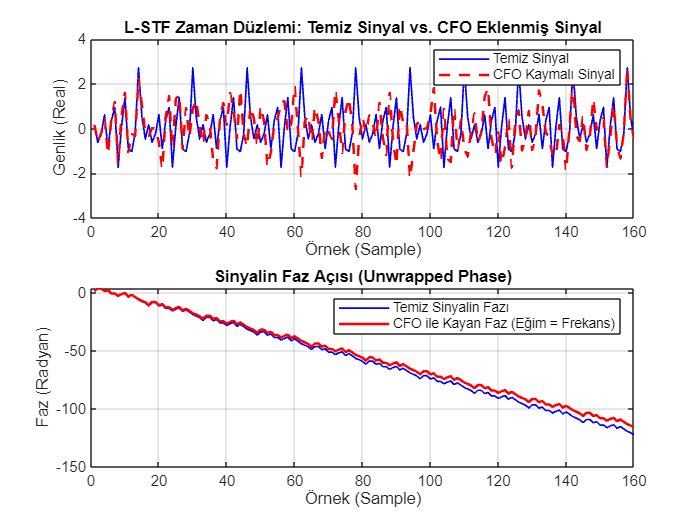

figure('Name', 'CFO Etkisi ve L-STF', 'Color', 'w');

% Temiz L-STF ile CFO'lu L-STF'nin gerçek kısımlarını karşılaştır
subplot(2,1,1);
plot(real(cleanPacket(1:160)), 'b', 'LineWidth', 1); hold on;
plot(real(packet_with_cfo(1:160)), 'r--', 'LineWidth', 1.5);
title('L-STF Zaman Düzlemi: Temiz Sinyal vs. CFO Eklenmiş Sinyal');
legend('Temiz Sinyal', 'CFO Kaymalı Sinyal');
xlabel('Örnek (Sample)');
ylabel('Genlik (Real)');
grid on;

% Faz açısındaki değişimi (dönmeyi) göster
subplot(2,1,2);
plot(unwrap(angle(cleanPacket(1:160))), 'b', 'LineWidth', 1); hold on;
plot(unwrap(angle(packet_with_cfo(1:160))), 'r', 'LineWidth', 1.5);
title('Sinyalin Faz Açısı (Unwrapped Phase)');
legend('Temiz Sinyalin Fazı', 'CFO ile Kayan Faz (Eğim = Frekans)');
xlabel('Örnek (Sample)');
ylabel('Faz (Radyan)');
grid on;